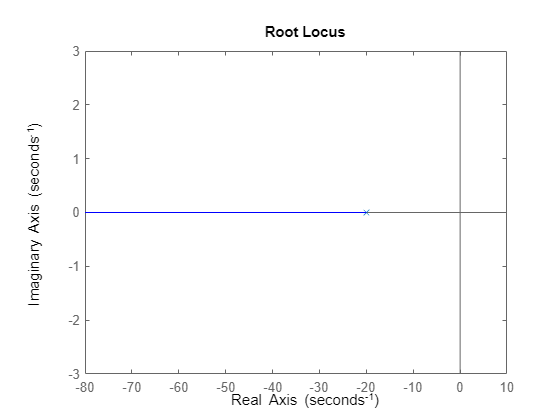

clearvars;
close all;
clc;



tau = 0.05;
K = 720/tau; % assume 720 deg/s max rate (throttle, u = [-1,1])
num = [K];
den = [tau 1];
G = tf(num, den);
rlocus(G);

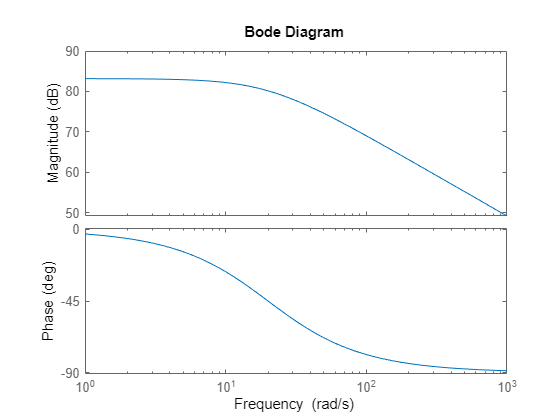

bode(G);

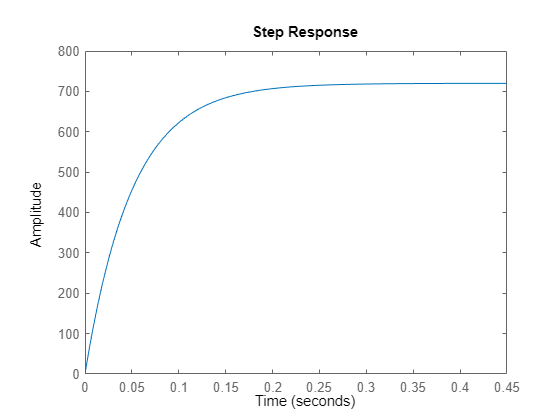


dt = 0.01;
A = [0, 1;
    0 -1/tau];
B = [0; K];
C = [0,1];
D = 0;
sys = ss(A, B, C, D);
dsys = c2d(sys, dt);
step(sys);

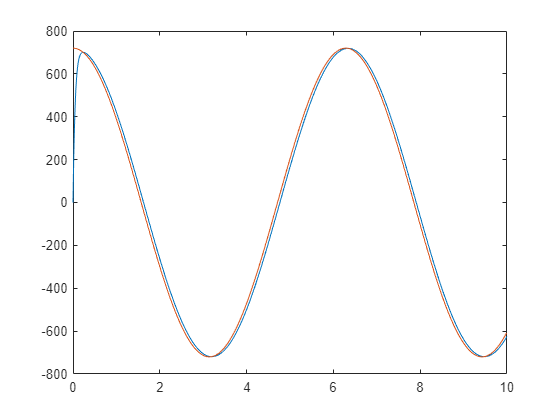



endtime = 10;
t = 0:dt:endtime;
x = nan(2,length(t));
u = nan(1,length(t));
x0 = [0;0];
x(:,1) = x0;

k = 1;
while t(k) < endtime
    u(k) = cos(t(k));
    x(:,k+1) = dsys.A*x(:,k) + dsys.B*u(k); 
    k = k+1;
end

plot(t, x(2,:), t, u*720);

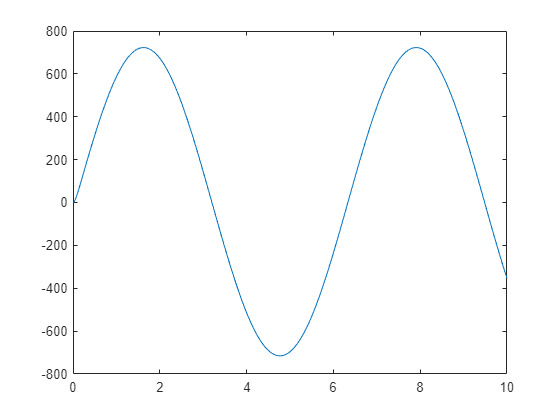

plot(t,x(1,:))

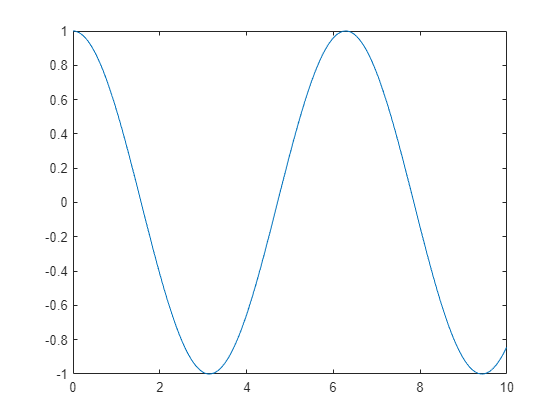

plot(t,u);